%simulate iemg data sets
table=readtable("../raw_data/Emg_for_fitting_DPF.xlsx");
x = table{:,1}; y = table{:,2};
[hill_a,hill_b,hill_c]=classic_hill(x,y);
data_Pcr  = readtable('../raw_data/Pcr_for_fitting_DPF.xlsx'); % Pcr force
cycle_index_exp=data_Pcr{:,1};
cycles=1:1:max(cycle_index_exp);
m=length(cycles);
init_iemg =((hill_a*(1^hill_b))/(1+hill_c))/100;
iemg_breaks=[1 0.3652];
sim_iemg=iemg_breaks'*ones(1,m);
sim_iemg=sim_iemg';
n=length(iemg_breaks);
for j=1:n
    a=0;
    for i=1:m
        a=((hill_a*(cycles(i)^hill_b))/(cycles(i)+hill_c))/100;
        if a<iemg_breaks(j)
            sim_iemg(i,j)=a;
        else
            break
        end
    end
end

% Simulate DPF cycles for the different iemg datasets
clear i j
load('params/solutions_SI.mat');
params = solutions(1,3).X;
force=zeros(m,n);
N_lvl=zeros(m,n);
Pi_lvl=zeros(m,n);
for i=1:n
    iemg_temp=sim_iemg(:,i);
    [Y]=eval_emg_SI(params,iemg_temp,m);
    force(:,i)=Y(:,6);
    Pi_lvl(:,i)=Y(:,1);
    N_lvl(:,i)=Y(:,7);
end

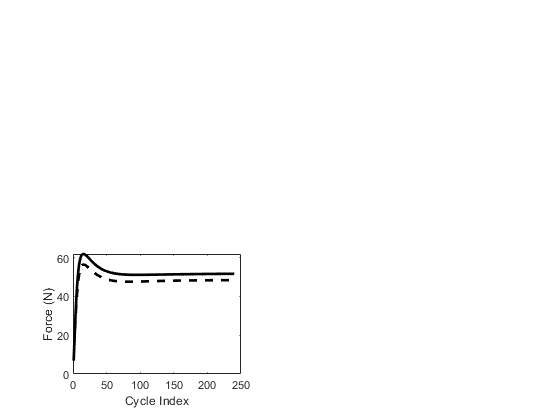

% Construct figure s3a
x=1:m;
figure(2);clf;
plot(x,force(:,1),'linewidth',2,'Color','k'); hold on;
plot(x,force(:,2),'linewidth',2,'Color','k','LineStyle','--');
xlim([0 250]);
ylim([0 inf]);
xlabel('Cycle Index');
ylabel('Force (N)');
set(gca,'Unit','Inches')
p = get(gca,'Position');
set(gca,'Unit','Inches','Position',[p(1) p(2) 1.75 1.25]);
exportgraphics(figure(2),fullfile('figure_8_subplots','figure_8_b.pdf'),'BackgroundColor','w','Resolution',300,'ContentType','vector');